# Quarter-Car Suspension Modeling and Simulation

**This project developed and evaluated a quarter-car suspension model using MATLAB, Simulink, and Simscape Multibody. The model represents one corner of a vehicle using a sprung mass, unsprung mass, suspension spring and damper, and tire compliance. The suspension was tested under a speed bump, pothole, and rough-road input. Automated performance metrics were used to evaluate ride comfort, suspension travel, and tire deflection. A parameter sweep was then performed to select improved suspension stiffness and damping values, followed by a robustness analysis.**

## Break Down the Problem

**In the space below, define the problem statement:**

The goal was to develop a quarter-car suspension model that provides acceptable ride comfort and road-holding performance across multiple road conditions. The model needed to calculate objective suspension metrics, automatically test each road case, and identify improved suspension spring and damping parameters.

**List the requirements, constraints, and success criteria for the project:**

The model was required to include a sprung mass, unsprung mass, suspension spring and damper, tire compliance, and a controllable road displacement input. The model was evaluated using sprung-mass acceleration, suspension travel, and tire deflection. The suspension parameters Ks and Cs were tuned while the remaining physical parameters were kept constant.

The road suite included a 0.075 m speed bump, a pothole, and a rough-road input. Automated testing compared the calculated metrics with the selected performance limits and generated a pass/fail summary.

**What is your proposed solution?**

A Simscape Multibody quarter-car model was connected to road inputs generated through the integrated Simulink model. Response signals were logged and processed using MATLAB. An automated runner evaluated all three road cases, and a nine part parameter sweep was used to compare combinations of suspension stiffness and damping.

**List the steps you will need to take to achieve your proposed solution:**

1. Build the baseline quarter-car model.

2. Create the speed-bump, pothole, and rough-road inputs.

3. Log the required response signals.

4. Calculate ride-comfort, travel, and tire-deflection metrics.

5. Automate the road-case simulations and pass/fail evaluation.

6. Sweep Ks and Cs across the selected parameter grid.

7. Select the design with the lowest average normalized score.

8. Validate the final design using a robustness test.

**What challenges do you face in the process of achieving the solution?**

The main challenges were integrating our work from multiple tasks, ensuring the scripts used the correct Simulink model, extracting logged signal data consistently, and maintaining consistent physical parameters across all simulations. The sprung and unsprung mass blocks were corrected to use the workspace parameters Ms and Mu rather than fixed geometry-calculated masses.

## Task 1: Build a baseline quarter-car multibody model

A baseline quarter-car suspension model was created in Simscape Multibody to represent the vertical motion of one corner of the vehicle. The model uses a sprung mass for the vehicle body and an unsprung mass for the wheel assembly. The two bodies are connected by a parameterized suspension spring and damper, while the wheel is connected to a vertically moving road through a compliant tire element.

The model was intentionally limited to vertical motion so that the suspension response could be evaluated without adding unnecessary rotational or lateral degrees of freedom. A prismatic road-input joint applies the road displacement, and the tire and suspension joints respond dynamically to that excitation.

The baseline physical parameters were:

`ms = 300 kg`

`mu = 40 kg`

`Ks = 18000 N/m`

`Cs = 1500 N·s/m`

`Kt = 180000 N/m`

`Ct = 100 N·s/m`

Three outputs were included in the model for later performance evaluation: sprung-mass vertical acceleration, suspension travel, and tire deflection. These signals were converted from Simscape physical signals to Simulink signals and used throughout the remaining tasks.

The model was first checked using a smooth road input to verify that the wheel responded to the road excitation, the body response was damped, and the system returned toward equilibrium after the disturbance. This baseline model was then used as the common vehicle model for the road-suite, automated testing, tuning, and robustness analysis.

**Baseline Quarter-Car Simscape Multibody Model**

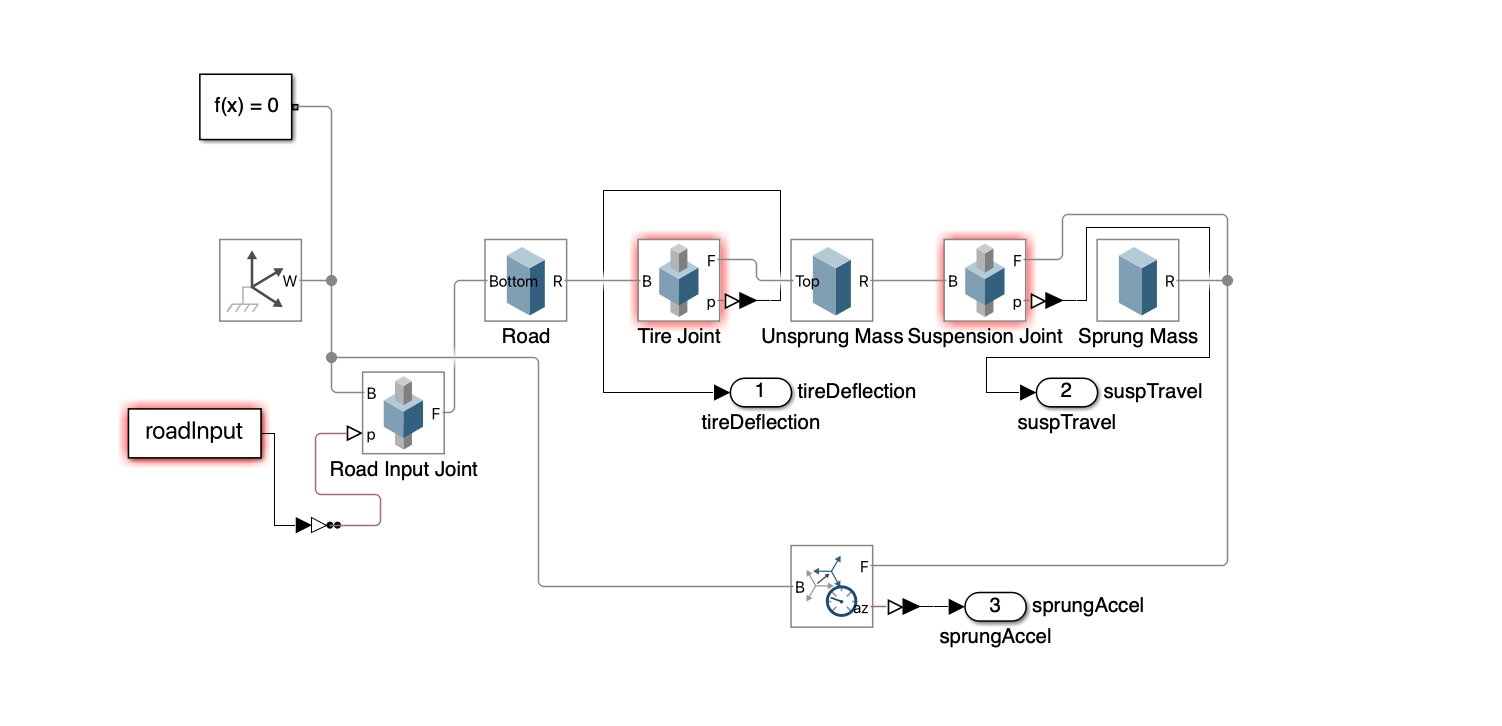

% Load the baseline quarter-car model and run a simulation
open_system("quarterCarModel_fixed.slx");


ms = 300;        % sprung mass [kg]
mu = 40;         % unsprung mass [kg]
Ks = 18000;      % suspension stiffness [N/m]
Cs = 1500;       % suspension damping [N*s/m]
Kt = 180000;     % tire stiffness [N/m]
Ct = 100;        % tire damping [N*s/m]

simOut = sim("quarterCarModel_fixed.slx", ...
    "ReturnWorkspaceOutputs","on");

Error evaluating expression 'Tstop' for 'StopTime' specified in the Configuration Parameters dialog for block diagram 'quarterCarModel_fixed'.

Caused by:
    Error using QuarterCar_Final_Report(1) (line 11)
    Unrecognized function or variable 'Tstop'.
        Error using QuarterCar_Final_Report(1) (line 11)
        Variable 'Tstop' does not exist. 

## Task 2: Create a road test suite (3-5 cases)

Three road profiles were created to test the quarter-car suspension under different types of road excitation: a speed bump, a pothole, and rough road.

The speed bump and pothole were created in the Signal Editor as smooth transient inputs. The speed bump was modeled as a positive smooth hump with a max height of 0.075 m, while the pothole was modeled as a smooth negative dip. Smooth profiles were used instead of step inputs to avoid unrealistic discontinuities.

The rough-road input was generated using a band-limited noise block. The three profiles were first created and verified in the standalone road-test model, then integrated into the final quarter-car model.

These three cases were used throughout Tasks 3–6 to evaluate comfort, suspension travel, tire deflection, parameter tuning, and robustness.

% Open the standalone road-test suite used to create the profiles
open_system("road_test_suite");


The speed bump and pothole profiles are stored in the Signal Editor block. The rough road case is generated by the rough-road subsystem. The full implementation is contained in `quarter_car_model_and_road_test.slx`.

The road profiles were first created and verified in the standalone `road_test_suite.slx` model. They were later integrated into `quarter_car_model_and_road_test.slx` for signal logging, automated testing, parameter tuning, and robustness validation.

**Speed Bump**

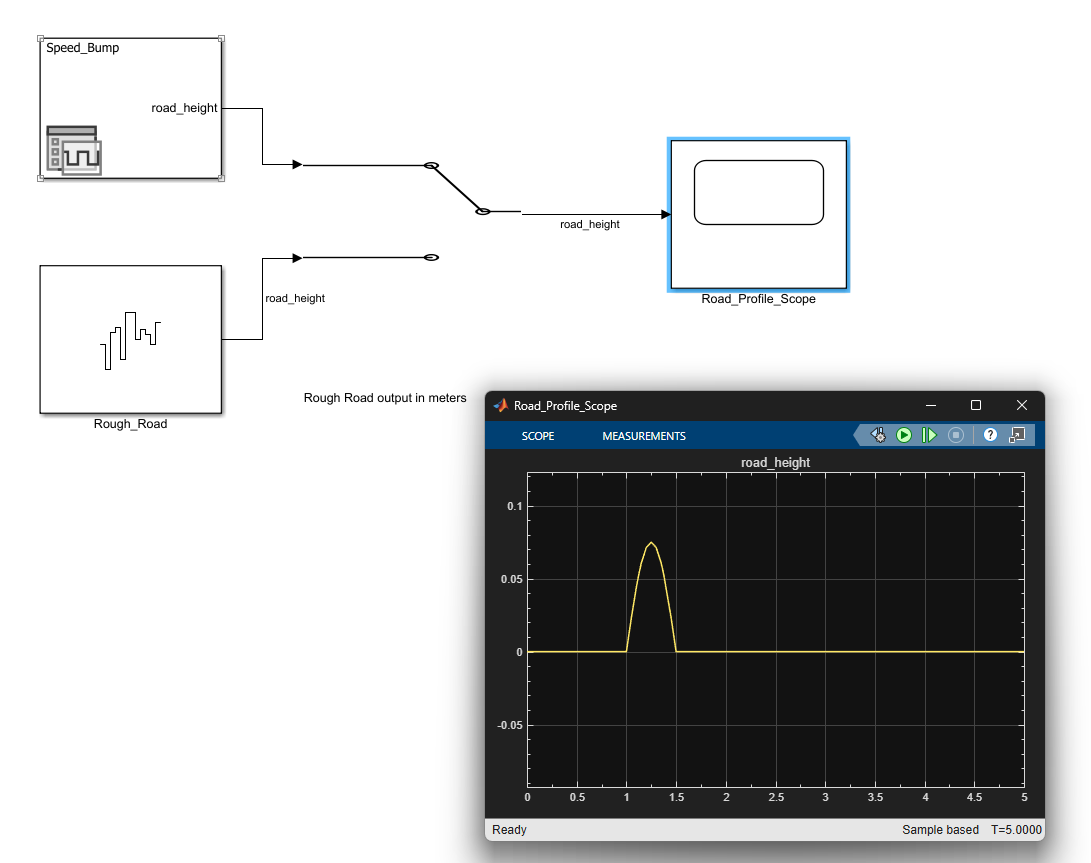

**Pothole**

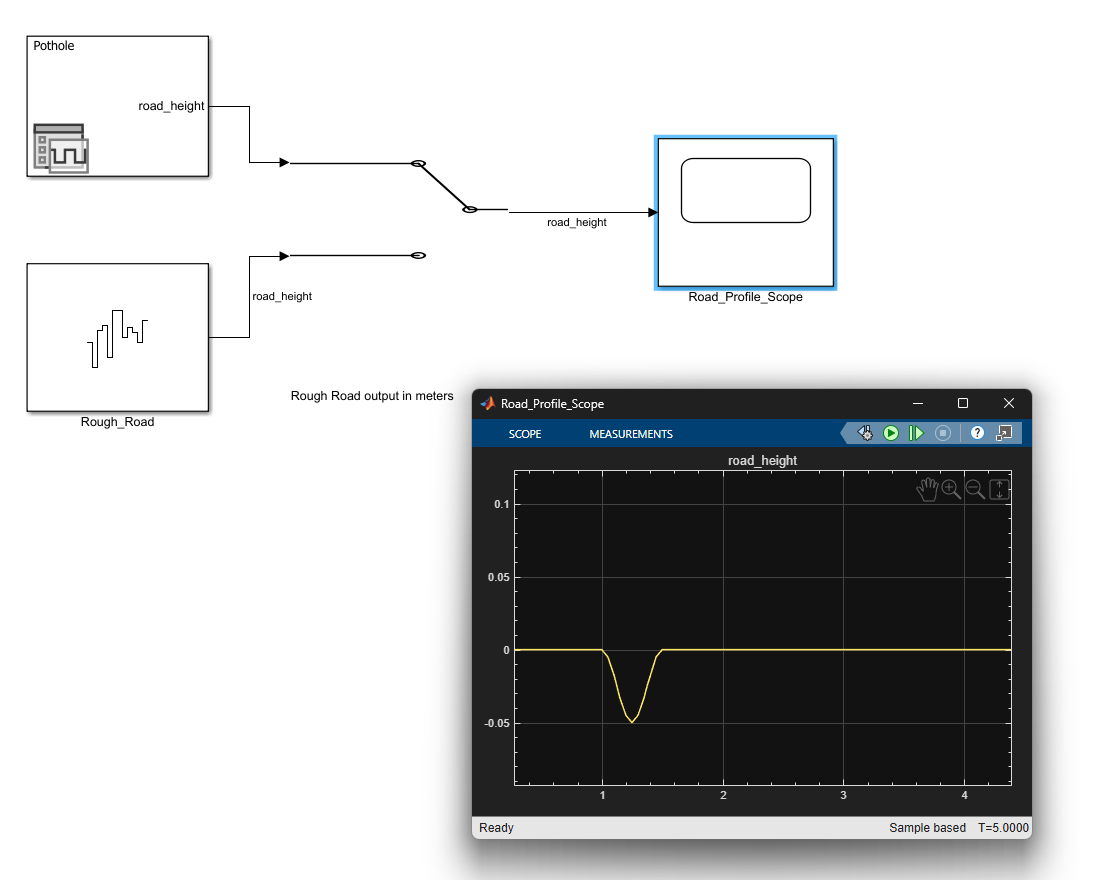

**Rough Road**

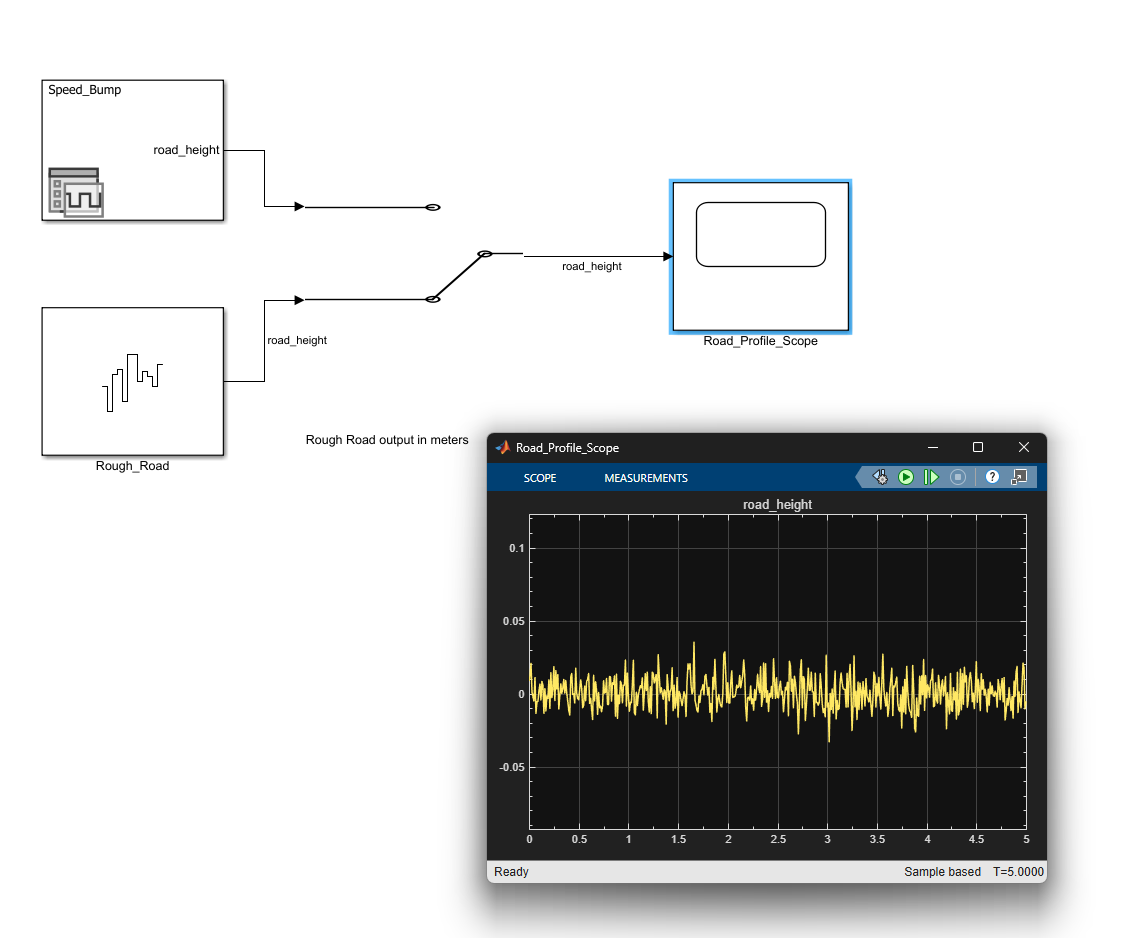

## Task 3: Log signals and define objective metrics

Log at minimum:

- Sprung-mass vertical acceleration

- Suspension travel (relative displacement)

- Tire deflection (relative wheel-to-road displacement) or normal-force proxy

Compute metrics per road case, such as:

- Comfort metric: RMS sprung acceleration (and/or peak)

- Packaging metric: max suspension travel

- Road-holding metric: max tire deflection (or variability)

Deliverable: a function like:

- returning a struct/table of metrics and a single “score”

% Insert your code here (or make use of helper functions or additional .m or .mlx files and indicate where
% they can be found). Ensure your code is well-documented.

    % Write your function here
end

## Task 4: Build an automated test runner

An automated MATLAB test runner was created to evaluate the quarter-car suspension across the three road cases developed in Task 2: the speed bump, pothole, and rough-road inputs. The purpose of the runner was to eliminate manual model changes and apply the same simulation and scoring procedure consistently to every road case.

For each test, the runner selects the correct road case from the integrated model using the Signal Editor scenario and Manual Switch. The same baseline vehicle parameters and scoring procedure are used for each simulation. The baseline vehicle parameters were also assigned programmatically so that the same physical model was used for every test.

After each simulation, the three response signals from Task 3—bodyAcceleration, suspensionTravel, and tireDeflection—were passed to the scoreSuspension function. The runner recorded RMS sprung-mass acceleration, peak acceleration, maximum suspension travel, maximum tire deflection, and the Task 3 weighted score.

The results from all road cases were combined into one summary table. In addition to the Task 3 score, the runner evaluates the comfort, suspension-travel, and tire-deflection requirements and reports a clear pass/fail result for each case. A single four-panel summary figure is also generated to compare the principal metrics across the three road profiles.

The project instructions specify the required metrics but do not provide numerical pass/fail limits. For the automated runner, editable design targets were therefore used: RMS body acceleration ≤ 3.0 m/s², peak body acceleration ≤ 8.0 m/s², maximum suspension travel ≤ 0.080 m, and maximum tire deflection ≤ 0.080 m. These values can be changed if different limits are required.

The automated test suite is run using the following script:

%% Task 4: Automated road-test runner
modelName = "quarter_car_model_and_road_test";

requirements = struct( ...
    "RMSAcceleration",3.0, ...       % m/s^2
    "PeakAcceleration",8.0, ...      % m/s^2
    "SuspensionTravel",0.080, ...    % m
    "TireDeflection",0.080);         % m

summaryTable = runAllTests(modelName,requirements);

disp(summaryTable)

The runAllTests_task4.m function loops through the three Task 2 road profiles, runs the model automatically, scores each simulation, and saves the results in the results_task4 folder. The exported deliverables are task4_summary_table.csv, task4_results.mat, task4_summary_figure.png, and task4_summary_figure.fig.

This automated workflow was then reused in Task 5 so that each candidate combination of Ks and Cs could be evaluated under the same road inputs and performance metrics.

## Task 5: Tune suspension parameters

A parameter sweep was used to tune the suspension spring stiffness, Ks�, and suspension damping coefficient, Cs�. The objective was to improve overall suspension performance across the speed-bump, pothole, and rough-road cases while considering ride comfort, suspension travel, and tire deflection.

The remaining model parameters were held constant:

`Ms = 300 kg`

`Mu = 40 kg`

`Kt = 180000 N/m`

`Ct = 100 N·s/m`

The baseline suspension values were:

`Ks = 18000 N/m`

`Cs = 1500 N·s/m`

Deliverable: chosen parameter values + justification using plots/tables.

% Parameter values tested
Ks_values = [15000 18000 21000];   % N/m
Cs_values = [1200 1500 1800];      % N*s/m

% Create the nine design combinations
[Ks_grid, Cs_grid] = ndgrid(Ks_values, Cs_values);

parameterGrid = table( ...
    Ks_grid(:), ...
    Cs_grid(:), ...
    'VariableNames', {'Ks_Npm','Cs_NsPm'});

disp(parameterGrid)

The parameter grid contained nine total suspension designs. Each combination was simulated for all three road cases using the integrated `quarter_car_model_and_road_test.slx` model. For each simulation, the RMS sprung-mass acceleration, peak sprung-mass acceleration, maximum suspension travel, and maximum tire deflection were calculated.

## Normalized scoring method

Each performance metric was normalized relative to the baseline design so that metrics with different units could be combined. A normalized value below 1 indicated improvement relative to the baseline, while a value above 1 indicated worse performance. Ride comfort was given the greatest weight in the combined score.

normalizedScore = ...
    normalizedAcceleration + ...
    0.5 * normalizedTravel + ...
    0.5 * normalizedTireDeflection; 

The baseline design therefore had a normalized score of 2.000

The best parameter combination differed between road cases, showing that no single suspension setting was optimal for every type of road input.

## Final Selected Design

To select one final design, the normalized scores from all three road cases were averaged for each parameter combination. The lowest overall average score occurred at: Ks = 21000 N/m Cs = 1200 N·s/m

The final design achieved an overall normalized score of 1.9414 compared with the baseline score of 2.0000, representing an improvement of approximately 2.9%. Although it was not the best design for every individual road case, it provided the best overall improvement across all three road profiles.

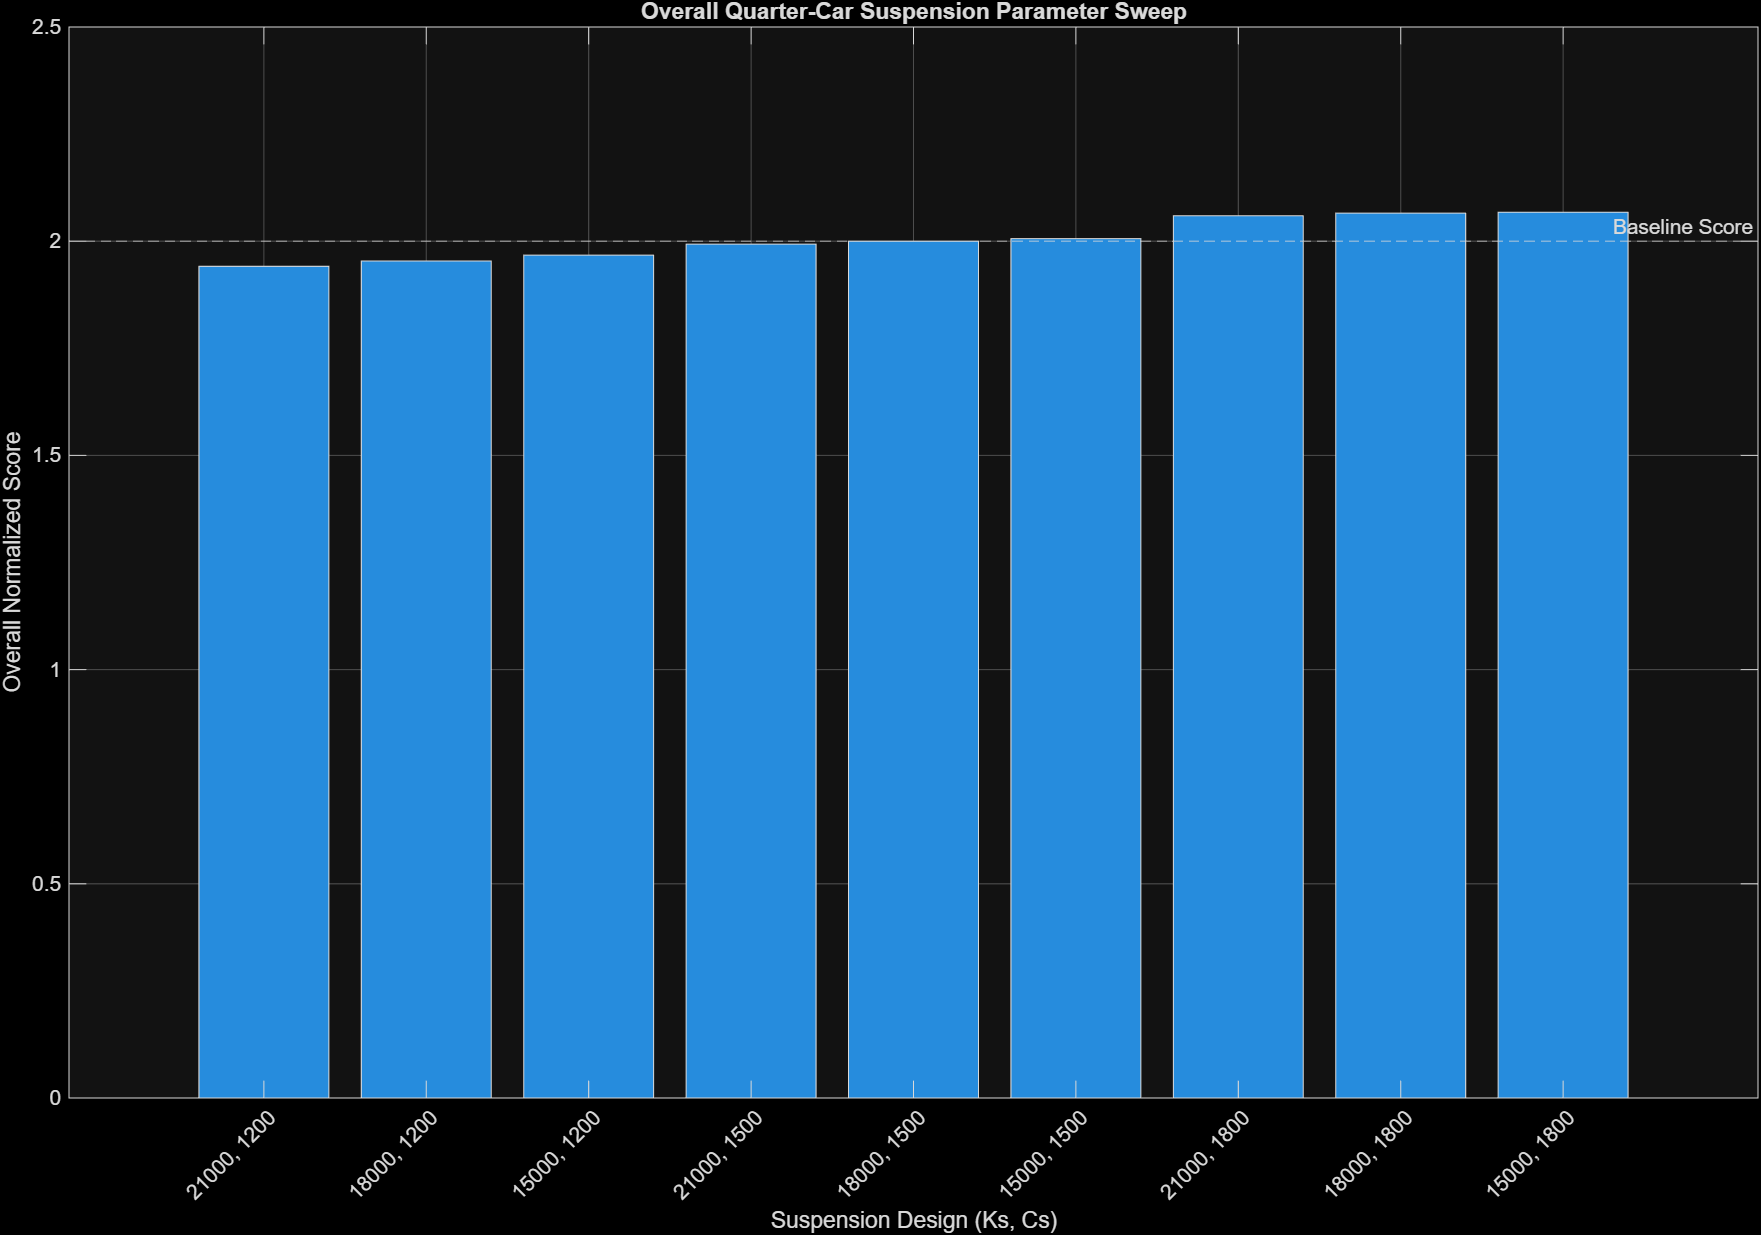

Lower bars represent better overall normalized performance, and the selected `Ks = 21000 N/m`, `Cs = 1200 N·s/m` design produced the minimum average score.

The full parameter sweep was implemented in `task5_setup.m`, and the combined comparison was completed in `task5_overall_results.m`.

## Task 6: Validate robustness with one simple variation

**Robustness Test Selected:** Payload Change (+25% Sprung Mass)

The sprung mass was increased by 25%, and the road test suite was rerun using the tuned suspension parameters. The worst-case metrics and overall pass rate are shown below.

Deliverable: a robustness summary (worst-case metrics and pass rate).

% Task 6 - Robustness Validation
% Increase the sprung mass by 25% and rerun the road test suite.

clear;
clc;
close all;

modelName = "quarter_car_model_and_road_test";

% Tuned suspension parameters from Task 5
Ms = 300 * 1.25;   % Sprung mass increased by 25%
Mu = 40;

ms = Ms;
mu = Mu;

Ks = 21000;
Cs = 1200;
Kt = 180000;
Ct = 100;

% Pass/fail performance criteria
requirements = struct( ...
    "RMSAcceleration", 3.0, ...
    "PeakAcceleration", 8.0, ...
    "SuspensionTravel", 0.080, ...
    "TireDeflection", 0.080);

% Road cases
roadCases = struct( ...
    "Name",        {"speedBump",  "pothole",   "roughRoad"}, ...
    "Scenario",    {"Speed_Bump", "Pothole",   ""}, ...
    "SwitchValue", {1,            1,           0}, ...
    "StopTime",    {5,            5,           5});

modelFile = which(modelName + ".slx");

if isempty(modelFile)
    error('Model file "%s.slx" was not found on the MATLAB path.', modelName);
end

resultsFolder = fullfile(pwd, "results");

if ~isfolder(resultsFolder)
    mkdir(resultsFolder);
end

% Put parameters in the base workspace before opening the model
assignin("base", "Ms", Ms);
assignin("base", "Mu", Mu);
assignin("base", "ms", ms);
assignin("base", "mu", mu);
assignin("base", "Ks", Ks);
assignin("base", "Cs", Cs);
assignin("base", "Kt", Kt);
assignin("base", "Ct", Ct);

load_system(modelName);

signalEditorPath = modelName + "/Signal Editor";
manualSwitchPath = modelName + "/Manual Switch";

resultsTable = table();

for k = 1:numel(roadCases)

    roadName = roadCases(k).Name;

    fprintf('Running Task 6 simulation %d/%d: %s\n', ...
        k, numel(roadCases), roadName);

    in = Simulink.SimulationInput(modelName);

    % Tuned suspension with 25% payload increase
    in = in.setVariable("Ms", Ms);
    in = in.setVariable("Mu", Mu);
    in = in.setVariable("ms", ms);
    in = in.setVariable("mu", mu);
    in = in.setVariable("Ks", Ks);
    in = in.setVariable("Cs", Cs);
    in = in.setVariable("Kt", Kt);
    in = in.setVariable("Ct", Ct);

    % Select road case
    in = in.setBlockParameter(manualSwitchPath, ...
        "CurrentSetting", num2str(roadCases(k).SwitchValue));

    if roadCases(k).Scenario ~= ""
        in = in.setBlockParameter(signalEditorPath, ...
            "ActiveScenario", roadCases(k).Scenario);
    end

    in = in.setModelParameter( ...
        "StopTime", num2str(roadCases(k).StopTime), ...
        "ReturnWorkspaceOutputs", "on", ...
        "SaveOutput", "on", ...
        "OutputSaveName", "yout", ...
        "SaveFormat", "Dataset");

    try
        simOut = sim(in);

        task3Input.logsout = simOut.get("yout");

        metrics = scoreSuspension(task3Input, roadName);

        comfortPass = ...
            metrics.rmsAccel <= requirements.RMSAcceleration && ...
            metrics.peakAccel <= requirements.PeakAcceleration;

        travelPass = ...
            metrics.maxTravel <= requirements.SuspensionTravel;

        tirePass = ...
            metrics.maxTireDefl <= requirements.TireDeflection;

        overallPass = comfortPass && travelPass && tirePass;

        row = table( ...
            string(metrics.road), ...
            metrics.rmsAccel, ...
            metrics.peakAccel, ...
            metrics.maxTravel, ...
            metrics.maxTireDefl, ...
            comfortPass, ...
            travelPass, ...
            tirePass, ...
            overallPass, ...
            "Completed", ...
            'VariableNames', { ...
            'Road', ...

Running Task 6 simulation 1/3: speedBump
Running Task 6 simulation 2/3: pothole
Running Task 6 simulation 3/3: roughRoad


            'RMSAcceleration_mps2', ...
            'PeakAcceleration_mps2', ...
            'MaxSuspensionTravel_m', ...
            'MaxTireDeflection_m', ...
            'ComfortPass', ...
            'TravelPass', ...
            'TirePass', ...
            'OverallPass', ...
            'SimulationStatus'});

    catch ME
        warning('Simulation failed for %s: %s', roadName, ME.message);

        row = table( ...
            string(roadName), ...
            NaN, ...
            NaN, ...
            NaN, ...
            NaN, ...
            false, ...
            false, ...
            false, ...
            false, ...
            "FAILED: " + string(ME.message), ...
            'VariableNames', { ...
            'Road', ...
            'RMSAcceleration_mps2', ...
            'PeakAcceleration_mps2', ...
            'MaxSuspensionTravel_m', ...
            'MaxTireDeflection_m', ...
            'ComfortPass', ...
            'TravelPass', ...
            'TirePass', ...
            'OverallPass', ...
            'SimulationStatus'});
    end

    resultsTable = [resultsTable; row]; %#ok<AGROW>
end

% Calculate worst-case metrics and pass rate
worstRMSAcceleration = max(resultsTable.RMSAcceleration_mps2);
worstPeakAcceleration = max(resultsTable.PeakAcceleration_mps2);
worstSuspensionTravel = max(resultsTable.MaxSuspensionTravel_m);
worstTireDeflection = max(resultsTable.MaxTireDeflection_m);

passedCases = nnz(resultsTable.OverallPass);
totalCases = height(resultsTable);
passRate = 100 * passedCases / totalCases;

robustnessSummary = table( ...
    Ms, ...
    Ks, ...
    Cs, ...
    worstRMSAcceleration, ...
    worstPeakAcceleration, ...


Task 6 Road-Case Results:


       Road        RMSAcceleration_mps2    PeakAcceleration_mps2    MaxSuspensionTravel_m    MaxTireDeflection_m    ComfortPass    TravelPass    TirePass    OverallPass    SimulationStatus
    ___________    ____________________    _____________________    _____________________    ___________________    ___________    __________    ________    ___________    ________________

    "speedBump"         0.0050856                 0.03395                0.00022244               0.075001             true          true         true          true          "Completed"   
    "pothole"           0.0032567                0.018143                0.00016277         


Task 6 Robustness Summary:


    SprungMass_kg    Ks_Npm    Cs_NsPm    WorstRMSAcceleration_mps2    WorstPeakAcceleration_mps2    WorstSuspensionTravel_m    WorstTireDeflection_m    PassedCases    TotalCases    PassRate_Percent
    _____________    ______    _______    _________________________    __________________________    _______________________    _____________________    ___________    __________    ________________

         375         21000      1200               0.26657                       1.2879                    0.00080181                 0.075001                3             3               100       



    worstSuspensionTravel, ...
    worstTireDeflection, ...

Road cases passed: 3 of 3


    passedCases, ...

Pass rate: 100.0%


    totalCases, ...
    passRate, ...
    'VariableNames', { ...
    'SprungMass_kg', ...
    'Ks_Npm', ...
    'Cs_NsPm', ...
    'WorstRMSAcceleration_mps2', ...
    'WorstPeakAcceleration_mps2', ...
    'WorstSuspensionTravel_m', ...
    'WorstTireDeflection_m', ...
    'PassedCases', ...
    'TotalCases', ...
    'PassRate_Percent'});

fprintf('\nTask 6 Road-Case Results:\n');
disp(resultsTable);

fprintf('\nTask 6 Robustness Summary:\n');
disp(robustnessSummary);

writetable(resultsTable, ...
    fullfile(resultsFolder, "task6_road_case_results.csv"));

writetable(robustnessSummary, ...
    fullfile(resultsFolder, "task6_robustness_summary.csv"));

fprintf('Road cases passed: %d of %d\n', passedCases, totalCases);
fprintf('Pass rate: %.1f%%\n', passRate);



## Interpretation of Results

**Summarize your findings by interpreting their physical/engineering meaning:**

The final quarter-car suspension model successfully met the project objectives. The automated test suite evaluated the suspension across multiple road conditions and compared each design using objective performance metrics. After tuning the suspension parameters, the final design provided a good balance between ride comfort, suspension travel, and tire deflection. The robustness test also showed that the tuned suspension met the performance requirements after increasing the sprung mass by 25%.

**What are some limitations of your work?**

The model represents only one corner of the vehicle rather than the entire vehicle. Only three road cases and a limited range of suspension parameters were tested. The robustness validation only considered a 25% increase in sprung mass.

**What are practical next steps?**

Additional road cases and suspension parameter values could be tested to further improve the design. Future work could also evaluate other vehicle conditions and extend the model to a half-car or full-vehicle model. This would provide a more complete representation of vehicle suspension performance.